**문제**

- 체적이 $1.2 \, \text{m}^3$인 밀폐된 용기에 밀도가 $0.025 \, \text{kg/m}^3$인 기체로 채워져 있을 때, 기체의 질량과 비체적은?

**풀이**

- **밀도 공식**: $\rho = \frac{m}{V}$�

- 여기서 $\rho$는 밀도, m은 질량, V는 부피입니다.

- **질량 계산**:

- 
$$m = \rho \times V$$


- 
$$m = 0.025 \, \text{kg/m}^3 \times 1.2 \, \text{m}^3$$


- 
$$m = 0.03 \, \text{kg}$$


- **비체적 계산**:

- 비체적 $v = \frac{1}{\rho}$�

- $v = \frac{1}{0.025 \, \text{kg/m}^3}$�

- 
$$v = 40 \, \text{m}^3/\text{kg}$$


**결과**

- **기체의 질량**: $0.03 \, \text{kg}$

- **비체적**: $40 \, \text{m}^3/\text{kg}$

% 밀도, 부피, 질량, 비체적 정의
density = 0.025; % kg/m^3
volume = 1.2; % m^3

% 질량 계산
mass = density * volume;

% 비체적 계산
specific_volume = 1 / density;

% 데이터 출력
fprintf('질량: %.2f kg\n', mass);

질량: 0.03 kg


fprintf('비체적: %.2f m^3/kg\n', specific_volume);

비체적: 40.00 m^3/kg


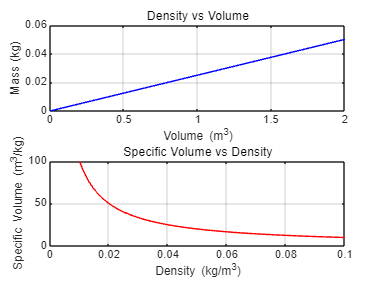


% 그래프 그리기
figure;

% 1. 밀도와 부피의 관계 그래프
subplot(2, 1, 1);
volumes = linspace(0, 2, 100); % 다양한 부피 값 생성
masses = density * volumes; % 각 부피에 대한 질량 계산
plot(volumes, masses, '-b');
xlabel('Volume (m^3)');
ylabel('Mass (kg)');
title('Density vs Volume');
grid on;

% 2. 비체적과 밀도의 관계 그래프
subplot(2, 1, 2);
densities = linspace(0.01, 0.1, 100); % 다양한 밀도 값 생성
specific_volumes = 1 ./ densities; % 각 밀도에 대한 비체적 계산
plot(densities, specific_volumes, '-r');
xlabel('Density (kg/m^3)');
ylabel('Specific Volume (m^3/kg)');
title('Specific Volume vs Density');
grid on;


% 그래프 표시

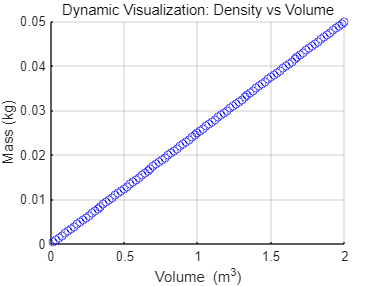

% 밀도, 부피 초기 값 정의
density = 0.025; % kg/m^3
volume_initial = 0; % 초기 부피
volume_final = 2; % 최종 부피
num_steps = 100; % 애니메이션 단계 수

% 애니메이션을 위한 figure 생성
figure;
hold on;
xlabel('Volume (m^3)');
ylabel('Mass (kg)');
title('Dynamic Visualization: Density vs Volume');
grid on;
xlim([volume_initial volume_final]);
ylim([0 density * volume_final]);

% 애니메이션 그리기
for i = 1:num_steps
    % 부피와 질량 계산
    volume = volume_initial + (volume_final - volume_initial) * (i / num_steps);
    mass = density * volume;
    
    % 그래프 업데이트
    plot(volume, mass, 'bo');
    pause(0.05); % 애니메이션 속도 조절
end

hold off;

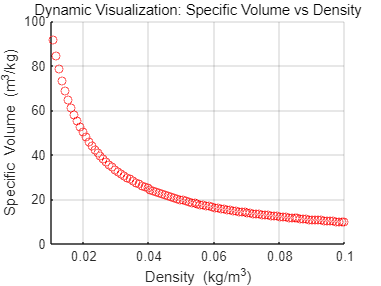


% 비체적과 밀도의 관계 애니메이션
figure;
hold on;
xlabel('Density (kg/m^3)');
ylabel('Specific Volume (m^3/kg)');
title('Dynamic Visualization: Specific Volume vs Density');
grid on;
xlim([0.01 0.1]);
ylim([0 100]);

% 밀도 변화에 따른 비체적 변화
for i = 1:num_steps
    % 밀도와 비체적 계산
    density_dynamic = 0.01 + (0.1 - 0.01) * (i / num_steps);
    specific_volume = 1 / density_dynamic;
    
    % 그래프 업데이트
    plot(density_dynamic, specific_volume, 'ro');
    pause(0.05); % 애니메이션 속도 조절
end

hold off;

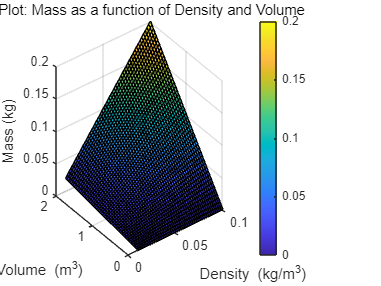

% 밀도와 부피 범위 설정
density_range = linspace(0.01, 0.1, 50); % kg/m^3
volume_range = linspace(0, 2, 50); % m^3

% 3D 그래프를 위한 격자 생성
[Density, Volume] = meshgrid(density_range, volume_range);

% 질량 계산
Mass = Density .* Volume;

% 3D 그래프 그리기
figure;
surf(Density, Volume, Mass);
xlabel('Density (kg/m^3)');
ylabel('Volume (m^3)');
zlabel('Mass (kg)');
title('3D Plot: Mass as a function of Density and Volume');
colorbar;
grid on;

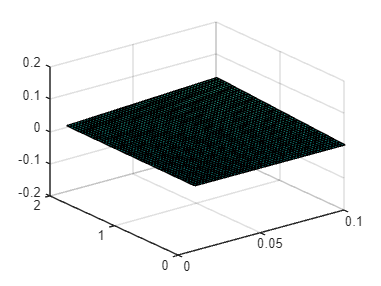

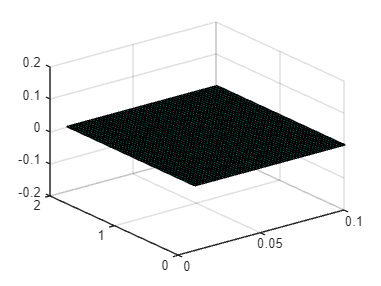

% 밀도와 부피 범위 설정
density_range = linspace(0.01, 0.1, 50); % kg/m^3
volume_range = linspace(0, 2, 50); % m^3

% 3D 그래프를 위한 격자 생성
[Density, Volume] = meshgrid(density_range, volume_range);

% 애니메이션을 위한 figure 생성
figure;
xlabel('Density (kg/m^3)');
ylabel('Volume (m^3)');
zlabel('Mass (kg)');
title('3D Dynamic Plot: Mass as a function of Density and Volume');
colorbar;
grid on;

% 애니메이션 그리기
for t = 1:50
    % 동적 밀도 및 부피에 따른 질량 계산
    Mass = Density .* Volume .* sin(2 * pi * t / 50); % 질량을 시간에 따라 변화시키기 위해 sin 함수 사용
    
    % 3D 그래프 업데이트
    surf(Density, Volume, Mass);
    zlim([-0.2 0.2]); % z축의 범위 고정
    caxis([-0.2 0.2]); % 색상 범위 고정
    pause(0.1); % 애니메이션 속도 조절
end

**문제**

- 400kgf의 하중이 단면적 $A = 25 \, \text{cm}^2$인 평판에 수평과 $30^\circ$를 이루며 작용할 때, 평판에 작용하는 압력(MPa)은?

**풀이**

- **힘 (F, 하중) 계산**:

- 하중을 뉴턴(N)으로 변환

- 
$$400 \, \text{kgf} = 400 \times 9.8 \, \text{N/kgf} = 3920 \, \text{N}$$


- **힘의 수직분력 계산**:

- 수평과 $30^\circ$를 이루므로 수직분력은 $F \sin \theta$

- 
$$\sin(30^\circ) = 0.5$$


- 
$$F \sin \theta = 3920 \times 0.5 = 1960 \, \text{N}$$


- **면적 (A) 계산**:

- 단면적을 제곱미터$\text{m}^2$로 변환

- 
$$25 \, \text{cm}^2 = 25 \times 10^{-4} \, \text{m}^2 = 2.5 \times 10^{-3} \, \text{m}^2$$


- **압력 (P) 계산**:

- 압력 $P = \frac{F}{A}$�

- $P = \frac{1960 \, \text{N}}{2.5 \times 10^{-3} \, \text{m}^2}$�

- 
$$P = 784000 \, \text{Pa}$$


- 
$$1 \, \text{MPa} = 10^6 \, \text{Pa}$$


- 
$$P = 0.784 \, \text{MPa}$$


% 주어진 값들
force_kgf = 400; % kgf
g = 9.8; % 중력 가속도 (m/s^2)
theta = 30; % 각도 (degrees)
area_cm2 = 25; % 면적 (cm^2)

% 1. 힘 (F, 하중) 계산
force_N = force_kgf * g; % kgf를 뉴턴(N)으로 변환
force_vertical = force_N * sind(theta); % 수직분력 계산

% 2. 면적 (A) 계산
area_m2 = area_cm2 / 10000; % cm^2를 m^2로 변환

% 3. 압력 (P) 계산
pressure_Pa = force_vertical / area_m2; % 압력 (Pa)
pressure_MPa = pressure_Pa / 10^6; % 압력을 MPa로 변환

% 값 출력
fprintf('수직분력: %.2f N\n', force_vertical);

수직분력: 1960.00 N


fprintf('면적: %.2e m^2\n', area_m2);

면적: 2.50e-03 m^2


fprintf('압력: %.3f MPa\n', pressure_MPa);

압력: 0.784 MPa


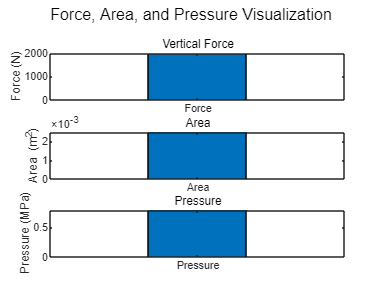


% 그래프 그리기
figure;

% 수직분력 그래프
subplot(3, 1, 1);
bar(1, force_vertical);
ylabel('Force (N)');
title('Vertical Force');
xticklabels({'Force'});

% 면적 그래프
subplot(3, 1, 2);
bar(1, area_m2);
ylabel('Area (m^2)');
title('Area');
xticklabels({'Area'});

% 압력 그래프
subplot(3, 1, 3);
bar(1, pressure_MPa);
ylabel('Pressure (MPa)');
title('Pressure');
xticklabels({'Pressure'});

% 그래프 표시
sgtitle('Force, Area, and Pressure Visualization');

**문제**

- 직경이 $50 \, \text{cm}$인 피스톤에서 $F_1 = 250 \, \text{kN}$의 힘을 얻기 위해서, 직경 $5 \, \text{cm}$인 피스톤에 가해야 할 힘 $F_2$�는?

**풀이**

- **파스칼의 원리**:

- 파스칼의 원리에 따르면 두 피스톤의 압력이 동일하므로,

$\frac{F_1}{A_1} = \frac{F_2}{A_2}A1$��

여기서,

- $F_1 = 250 kN$ (주어진 힘)

- $A_1 = \frac{\pi d_1^2}{4}$ (큰 피스톤의 면적)

- $A_2 = \frac{\pi d_2^2}{4}$�� (작은 피스톤의 면적)

- 직경 $d_1 = 50 \, \text{cm}$

- 직경 $d_2 = 5 \, \text{cm}$

- **힘 계산**:

- 면적 비례 관계:

$F_2 = \left( \frac{d_2}{d_1} \right)^2 \times F_1$�

- 값 대입:


$$F_2 = \left( \frac{5}{50} \right)^2 \times 250 \, \text{kN}$$


- 
$$F_2 = \left( \frac{1}{10} \right)^2 \times 250$$


- 
$$F_2 = \frac{1}{100} \times 250$$


- 
$$F_2 = 2.5 \, \text{kN}$$


**결과**

- **작은 피스톤에 가해야 할 힘 **$F_2: 2.5 \, \text{kN}$

% 주어진 값들
F1 = 250; % kN
d1 = 50; % cm
d2 = 5; % cm

% 힘 계산
F2 = (d2/d1)^2 * F1; % kN

% 값 출력
fprintf('작은 피스톤에 가해야 할 힘 F2: %.2f kN\n', F2);

작은 피스톤에 가해야 할 힘 F2: 2.50 kN


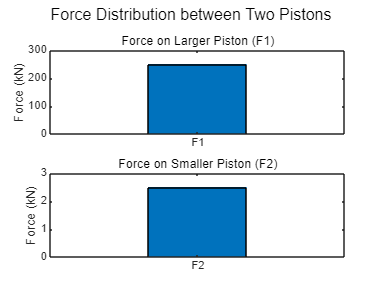


% 그래프 그리기
figure;

% 큰 피스톤의 힘
subplot(2, 1, 1);
bar(1, F1);
ylabel('Force (kN)');
title('Force on Larger Piston (F1)');
xticklabels({'F1'});

% 작은 피스톤의 힘
subplot(2, 1, 2);
bar(1, F2);
ylabel('Force (kN)');
title('Force on Smaller Piston (F2)');
xticklabels({'F2'});

% 그래프 표시
sgtitle('Force Distribution between Two Pistons');

**문제**

- 실린더 내부의 가열된 가스 압력이 $2.2 \, \text{MPa}$입니다.

- 피스톤의 지름이 $36 \, \text{cm}$일 때, 피스톤을 고정하기 위해 필요한 힘 F는 얼마인가요?

**풀이**

- **압력과 면적 관계**:

- 압력 (P)과 면적 (A)을 이용하여 힘 (F)을 계산할 수 있습니다.

- 공식: $F = P \times A$

- 여기서,

- 
$$P = 2.2 \, \text{MPa} = 2200 \, \text{kN/m}^2$$


- 피스톤의 지름 $(d) = 36\,\text{cm} = 0.36 \, \text{m}$

- **면적 계산**:

- 원형 피스톤의 면적 (A):


$$A = \frac{\pi d^2}{4} = \frac{\pi \times (0.36)^2}{4} \, \text{m}^2$$


- **힘 계산**:

- 
$$F = P \times A$$



$$F = 2200 \times \frac{\pi \times (0.36)^2}{4} \, \text{kN}$$


- 
$$F = 2200 \times 0.1017 = 223.93 \, \text{kN}$$


**결과**

- **피스톤을 고정하기 위해 필요한 힘 F**: $223.93 \, \text{kN}$

% 주어진 값들
pressure_MPa = 2.2; % MPa
pressure_kN_m2 = pressure_MPa * 1000; % kN/m^2
diameter_m = 0.36; % m

% 면적 계산
area_m2 = pi * (diameter_m^2) / 4;

% 힘 계산
force_kN = pressure_kN_m2 * area_m2;

% 값 출력
fprintf('면적: %.4f m^2\n', area_m2);

면적: 0.1018 m^2


fprintf('필요한 힘 F: %.2f kN\n', force_kN);

필요한 힘 F: 223.93 kN


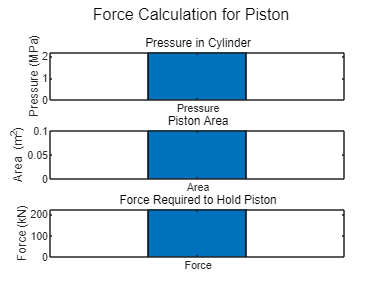


% 그래프 그리기
figure;

% 압력 그래프
subplot(3, 1, 1);
bar(1, pressure_MPa);
ylabel('Pressure (MPa)');
title('Pressure in Cylinder');
xticklabels({'Pressure'});

% 면적 그래프
subplot(3, 1, 2);
bar(1, area_m2);
ylabel('Area (m^2)');
title('Piston Area');
xticklabels({'Area'});

% 힘 그래프
subplot(3, 1, 3);
bar(1, force_kN);
ylabel('Force (kN)');
title('Force Required to Hold Piston');
xticklabels({'Force'});

% 그래프 표시
sgtitle('Force Calculation for Piston');

**문제**

- 대기압력이 $1 \, \text{atm}$인 상태에서 장치의 진공게이지 압력이 $230 \, \text{mmHg}$라고 할 때, 절대압력 ($\text{kPa}$)은?

**풀이**

- **절대압력 (**$P_{abs}$**�****) 공식**:

- $P_{abs} = P_{atm} - P_{vac}$�

- 여기서,

- 
$$P_{atm} = 대기압 = 101.325 \, \text{kPa}$$


- 
$$P_{vac} = 진공게이지 압력$$


- **진공게이지 압력을 **$\text{kPa}$**로 변환**:

- 
$$1 \, \text{atm} = 760 \, \text{mmHg} = 101.325 \, \text{kPa}$$


- 따라서 $230 \, \text{mmHg}$ 는 $\text{kPa}$로 변환하면,


$$P_{vac} = 230 \times \left( \frac{101.325}{760} \right) \, \text{kPa} = 30.665 \, \text{kPa}$$


- **절대압력 계산**:

- 
$$P_{abs} = 101.325 \, \text{kPa} - 30.665 \, \text{kPa}$$


- 
$$P_{abs} = 70.66 \, \text{kPa}$$


**결과**

- **절대압력 **$P_{abs}$**�**: $70.66 \, \text{kPa}$

% 주어진 값들
P_atm_kPa = 101.325; % 대기압 (kPa)
P_vac_mmHg = 230; % 진공게이지 압력 (mmHg)

% 진공게이지 압력을 kPa로 변환
P_vac_kPa = P_vac_mmHg * (P_atm_kPa / 760);

% 절대압력 계산
P_abs_kPa = P_atm_kPa - P_vac_kPa;

% 값 출력
fprintf('대기압: %.3f kPa\n', P_atm_kPa);

대기압: 101.325 kPa


fprintf('진공게이지 압력: %.3f kPa\n', P_vac_kPa);

진공게이지 압력: 30.664 kPa


fprintf('절대압력: %.3f kPa\n', P_abs_kPa);

절대압력: 70.661 kPa


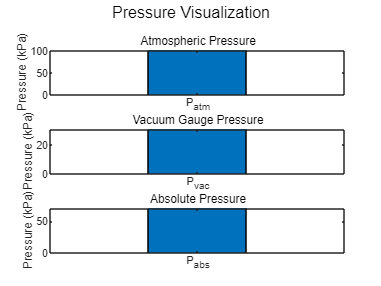


% 그래프 그리기
figure;

% 대기압 그래프
subplot(3, 1, 1);
bar(1, P_atm_kPa);
ylabel('Pressure (kPa)');
title('Atmospheric Pressure');
xticklabels({'P_{atm}'});

% 진공게이지 압력 그래프
subplot(3, 1, 2);
bar(1, P_vac_kPa);
ylabel('Pressure (kPa)');
title('Vacuum Gauge Pressure');
xticklabels({'P_{vac}'});

% 절대압력 그래프
subplot(3, 1, 3);
bar(1, P_abs_kPa);
ylabel('Pressure (kPa)');
title('Absolute Pressure');
xticklabels({'P_{abs}'});

% 그래프 표시
sgtitle('Pressure Visualization');